clear
clc
close all

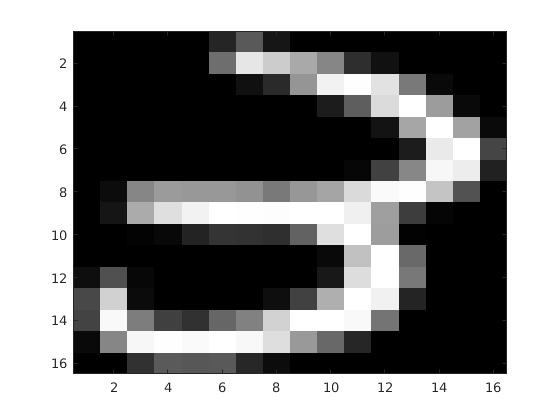

% Loading data
load threes -ascii

% Visualising image
colormap('gray');
imagesc(reshape(threes(1,:),16,16),[0,1]);

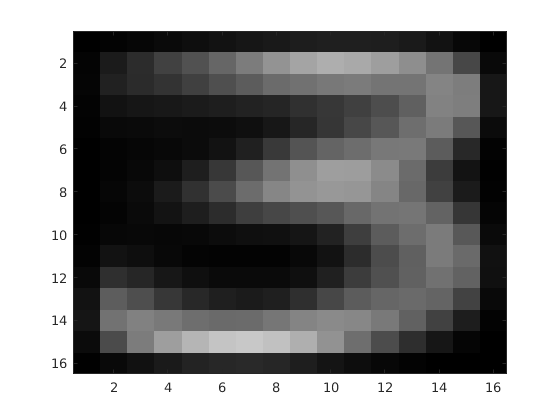


% Calculating and visualising the mean '3'
mean3 = mean(threes);
imagesc(reshape(mean3(1,:),16,16),[0,1]);

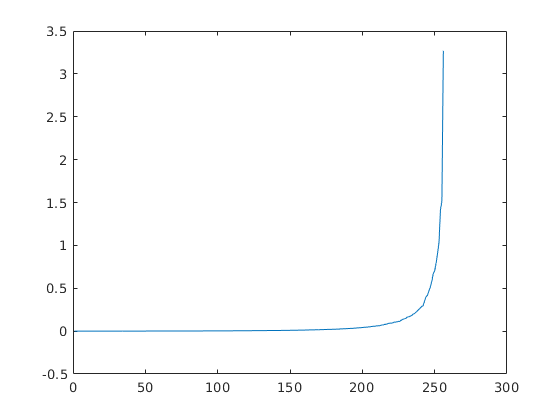

% Changing variable name for readability
data = threes';

%Calculate the mean of each column
mean_vector = mean(data,1);

%Zero mean the dataset by subtracting the mean
zero_data = data - mean_vector;

% Computing the covariance matrix
covariance = cov(zero_data');

% Computing eigenvectors and eigenvalues of covariance matrix
[vectors,values] = eig(covariance);
eigenvalues = diag(values);
sum_eigenvalues = sum(eigenvalues);

% Plotting eigenvalues
plot(eigenvalues);

%Setting size of projected dim ension
q = 50;

%Initialise errors and eigenvalue-percentages arrays
errors = zeros(1,q);
var_subs = zeros(1,q);

for i=1:q
    %Compute the reduced eigenvalues and eigenvactors of the covariance matrix
    [E, reduced_values] = eigs(covariance, i);
    sum_reduced_values = sum(diag(reduced_values));
    
    %Compute the percentage of variance captured by subspace
    var_sub = sum_reduced_values/sum_eigenvalues;
    var_subs(1,i) = var_sub;
    
    %Compute transpose of reduced eigenvectors
    E_T = E';
    
    %Reduce the dataset by multipling with E_T
    reduced_data = E_T*data;
    
    %Generate reconstructed dataset from reduced dataset
    reconstructed_data_0 = E*reduced_data;
    reconstructed_data = reconstructed_data_0 + mean_vector;
    
    %Estimate the error
    RMSD = sqrt(mean(mean((data-reconstructed_data).^2)));
    errors(1,i) = RMSD;
end

max(var_subs)

ans = 0.9121

min(errors)

ans = 0.1033

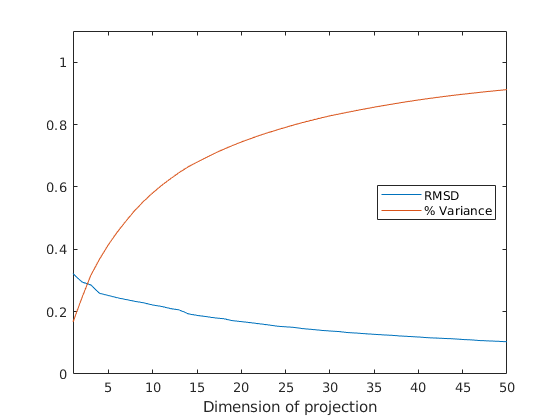


%Plotting RMSD for different q-values
plot(errors);
hold on;
plot(var_subs);
xlabel('Dimension of projection')
xlim([1 q]);
ylim([0 1.1]);
legend({'RMSD','% Variance'},'Location','east')
hold off;

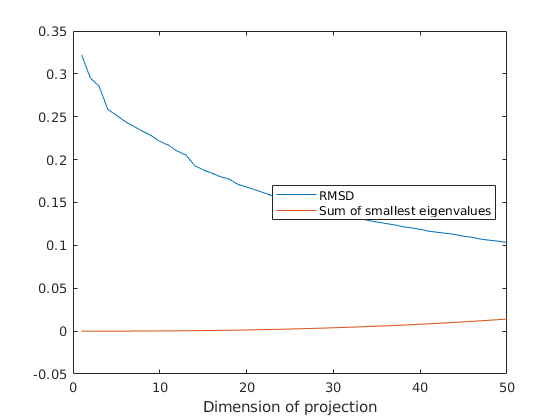

% Get a sorted array of eigenvalues
eigenvalues = sort(diag(values))';

% Returning the cumulative sum of i smallest eigenvalues
i_smallest = cumsum(eigenvalues);
plot_q_small = i_smallest(1,1:q);

% Comparing with the reconstruction errors
plot(errors);
hold on;
plot(plot_q_small);
xlabel('Dimension of projection')
%xlim([1 q]);
%ylim([0 1.1]);
legend({'RMSD','Sum of smallest eigenvalues'},'Location','east')
hold off;